clear;
clc;
addpath("../interpolation/")

## Objective

duration = 1;
times = 0:0.1:duration;
% times = 0:0.01:1;
len = size(times, 2);
force_square_obj = @(x) trapz(times, x(2*len+1:3*len).^2);
absolute_work = @(x) trapz(times, abs(x(2*len+1:3*len).*x(len+1:2*len)));

## Formulation

LB = [ones(len, 1)*(-inf); ones(len, 1)*(-inf); ones(len, 1)*(-30)]; %Lower Bounds
UB = [ones(len, 1)*(inf); ones(len, 1)*(inf); ones(len, 1)*(30)]; %Upper Bounds

X0 = zeros(3*len, 1); %Initial Condition

A = []; %No linear inequality constraints
B = [];

Aeq = []; %No linear equality constraints
Beq = [];

options = optimoptions('fmincon',...
                       'Algorithm', 'sqp',...
                       'Display', 'iter-detailed',...
                       'MaxFunctionEvaluations', 100000,...
                       'MaxIterations', 2000,...
                       'FunctionTolerance', 1e-10);

pos_target = 1;

## Solve NLP

[X, Cost] = fmincon(@(x) force_square_obj(x), X0, A, B, Aeq, Beq, LB, UB,...
            @(x) direct_collocation_constraints(x, times, pos_target), options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          34    0.000000e+00     1.000e+00     1.000e+00     0.000e+00     1.490e-09  
    1          68    1.320753e+01     1.554e-15     1.000e+00     1.263e+01     4.606e+00  
    2         102    1.304727e+01     4.483e-10     1.000e+00     4.112e-01     2.407e-01  
    3         136    1.257009e+01     1.999e-09     1.000e+00     1.822e+00     1.040e-01  
    4         170    1.246138e+01     9.199e-10     1.000e+00     1.378e+00     6.717e-03  
    5         204    1.246127e+01     2.847e-11     1.000e+00     1.141e-02     5.425e-03  
    6         238    1.246106e+01     1.233e-10     1.000e+00     4.562e-02     4.814e-05  
    7         272    1.246106e+01     1.793e-12     1.000e+00     3.285e-04     4.228e-05  
    8         306    1.246106e+01     3.053e-13     1.000e+00     1.224e-04     3.

## Plot

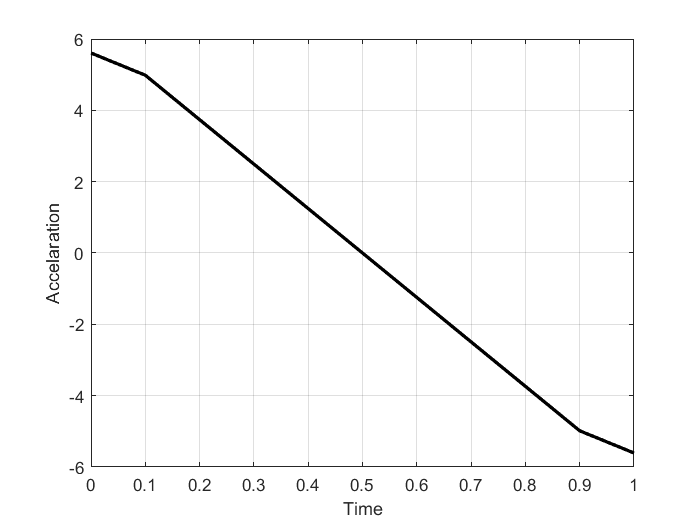

pos = X(1:len);
vel = X(len+1:2*len);
acc = X(2*len+1:3*len);

figure(1);
plot(times, acc,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Accelaration');

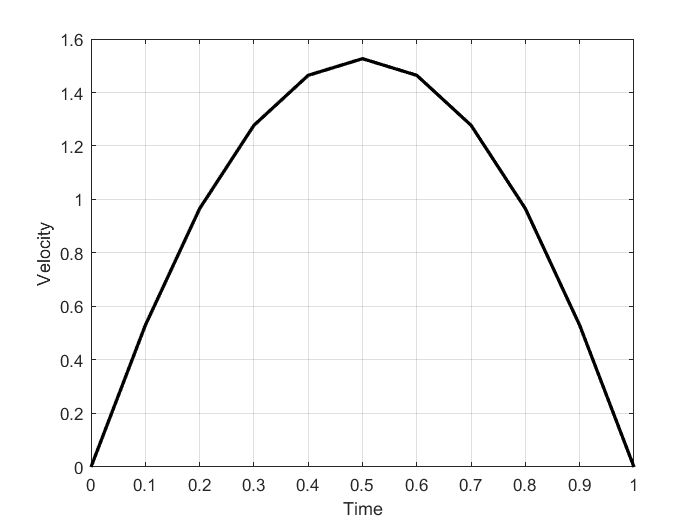


figure(2);
plot(times, vel,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Velocity');

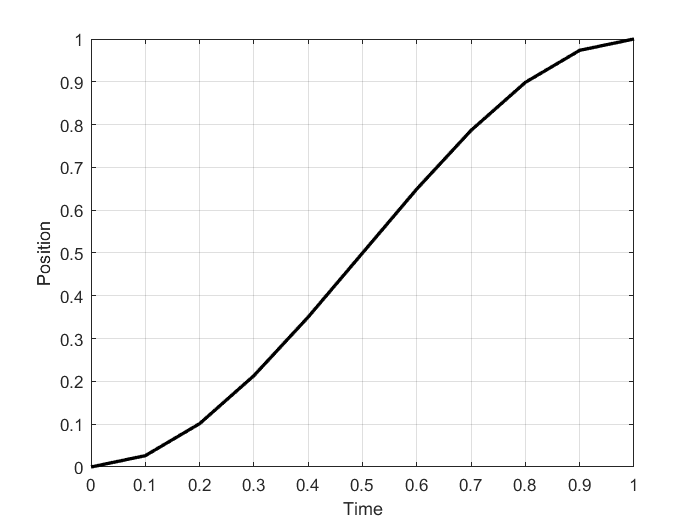


figure(3);
plot(times, pos,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Position');

## Interpolation

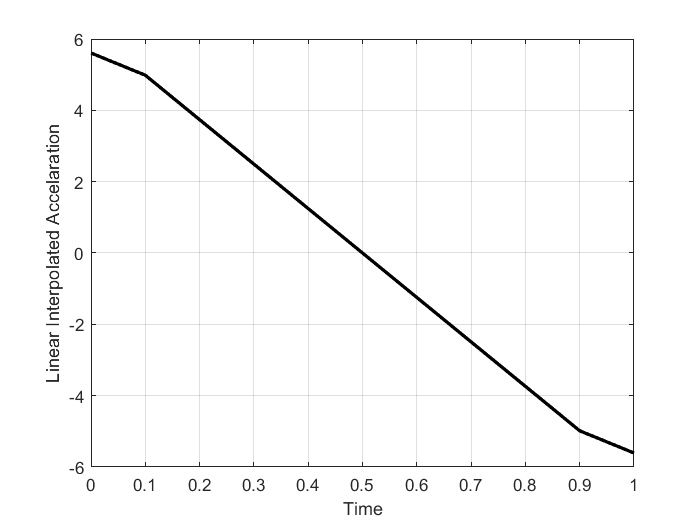

tm = 0:0.001:duration;

acc_i = [];
for i = 1:size(tm, 2)
    acc_i = [acc_i, linear_interpolate(times, acc, tm(i))];
end
figure(4);
plot(tm, acc_i,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Linear Interpolated Accelaration');

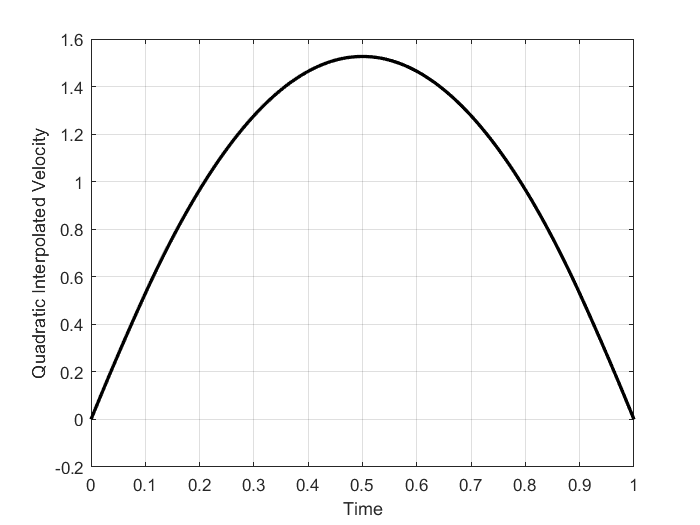

vel_i = [];
for i = 1:size(tm, 2)
    vel_i = [vel_i; quadratic_interpolate(times, vel, acc, tm(i))];
end
figure(4);
plot(tm, vel_i,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Quadratic Interpolated Velocity');

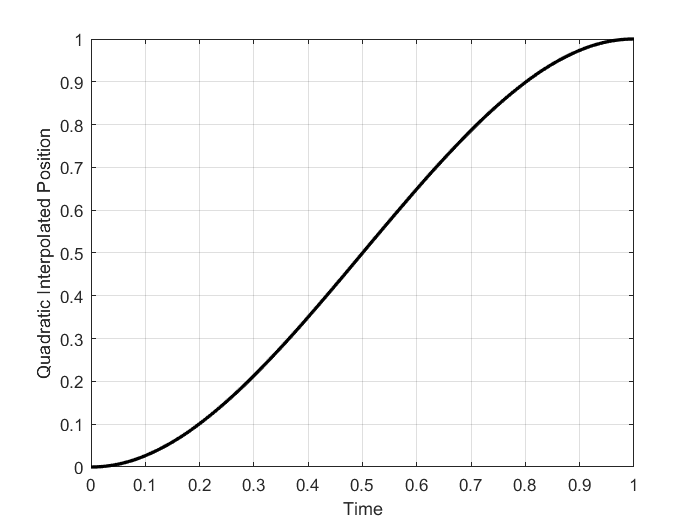


pos_i = [];
for i = 1:size(tm, 2)
    pos_i = [pos_i; quadratic_interpolate(times, pos, vel, tm(i))];
end
figure(4);
plot(tm, pos_i,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Quadratic Interpolated Position');